Author: **Arjan Gupta**

Due: April 3, 2023

Class: RBE 501

Institution: Worcester Polytechnic Institute

clear; close all; clc;

## Preliminary Setup

### Build Denso's HSR robot with Robotics Toolkit

In the prompt of this assignment, we are given the following table.


$$\matrix{
\text{Link}    	& a_i 	& \alpha_i &  d_i & \theta_i  \cr
1			& 205 			& 0	& 220	& \theta_1			\cr
2			& 275 			& 0		& 0	& \theta_2		\cr
3			& 0 			& 0			& d_3 & 0	\cr
4	        & 0 			& 0 		    & 0 & \theta_4					\cr
}$$


To implement this, we first define joint variables.

theta1 = 0;
theta2 = 0;
d3 = 0;
theta4 = 0;

Now, we can import the DH params from the given table.

% Link lengths
L1 = sqrt((205)^2 + (220)^2)/1000;
L2 = 0.275;
% DH parameters
dhparams = [0.205   0   	0.220   theta1;
            0.275	0       0       theta2;
            0   	0	    d3	    0;
            0       0       0       theta4];

Next, we create a rigid body tree object to build the Denso HSR robot. This is necessary to begin assigning rigid bodies (links) of the robot, to represent moving parts.

denso_robot = rigidBodyTree("DataFormat","column");

We can begin building the robot now. We make sure that the order of the joints is revolute, revolute, prismatic, revolute. This is because, as shown in the information web-page of Denso Robotics, the HSR robot is essentially a SCARA robot with a revolute tool-tip.

As described in the tutorial of the Robotics Toolkit, we need to assign bodies and joints, as shown in the following code.

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','prismatic');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');

We can then set their transforms (this is done by using rows of the DH table we are given). 

setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');

Joints also need to be associated with their bodies, as shown in the following code.

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;

Finally, bodies can be assigned to the rigid-body tree.

addBody(denso_robot,body1,'base')
addBody(denso_robot,body2,'body1')
addBody(denso_robot,body3,'body2')
addBody(denso_robot,body4,'body3')

We can verify that our robot was built correctly by showing its details.

showdetails(denso_robot)

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


### Show target positions

In the video, the robot picks up the 4 sets of water bottles and moves them to new locations (this sequence is the first 8 moves/goal positions). Then it picks them up again, in a different order, and puts them back in the starting positions (another 8 moves). In the following set of goal positions, we have shown the first 8 positions from the video. For our angles, we have chosen estimated values such that the end-effector lies on the 180 degree arc.

goalPos = zeros(4,1,8);

The following is the first position of the robot shown in the video, i.e. when the robot picks up the first set of water bottles.

goalPos(:,:,1) = [deg2rad(0);deg2rad(0);-0.2;0]; % Goal position 1

Similarly, set the positions where the robot drops off the first set of water bottles,

goalPos(:,:,2) = [deg2rad(50);deg2rad(15);-0.2;0]; % Goal position 2

picks up the second set of water bottles,

goalPos(:,:,3) = [deg2rad(7.5);deg2rad(7.5);-0.2;0]; % Goal position 3

drops off the second set of water bottles,

goalPos(:,:,4) = [deg2rad(55);deg2rad(35);-0.2;0]; % Goal position 4

picks up the third set of water bottles,

goalPos(:,:,5) = [deg2rad(180);deg2rad(0);-0.2;0]; % Goal position 5

drops off the third set of water bottles,

goalPos(:,:,6) = [deg2rad(140);deg2rad(-25);-0.2;0]; % Goal position 6

picks up the fourth set of water bottles,

goalPos(:,:,7) = [deg2rad(160);deg2rad(5);-0.2;0]; % Goal position 7

drops off the fourth set of water bottles,

goalPos(:,:,8) = [deg2rad(115);deg2rad(-15);-0.2;0]; % Goal position 8

picks up the third set of water bottles,

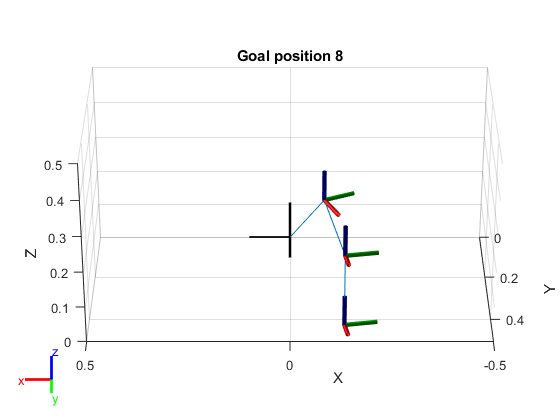

for i = 1:8
    show(denso_robot,goalPos(:,:,i));
    axis([-0.500,0.500,0,0.500,0,0.500]) % Set axes to be like video
    view(180,30) % Adjust camera view
    title(sprintf("Goal position %d",i))
    pause(1)
end

### Set Physical Properties

Set masses and moments of inertia.

% Masses for links (in kgs)
linkMass = zeros(4,1);
linkMass(1) = 3.0;
linkMass(2) = 2.75;
linkMass(3) = 2.0;
linkMass(4) = 1;
% Moments of inertia (in kgm^2)
I1 = 0.1;
I2 = 0.1;
I3 = 0; % prismatic
I4 = 0.01;
% Set the masses
body1.Mass = linkMass(1);
body2.Mass = linkMass(2);
body3.Mass = linkMass(3);
body4.Mass = linkMass(4);
% Set the centers of masses
body1.CenterOfMass = [L1/2, 0, 0];
body2.CenterOfMass = [L2/2, 0, 0];
body3.CenterOfMass = [d3/2, 0, 0]; % variable prismatic length
body4.CenterOfMass = [0,0,0];
% Set the inertias
body1.Inertia = [I1,I1,I1,0,0,0];
body2.Inertia = [I2,I2,I2,0,0,0];
body3.Inertia = [0,0,0,0,0,0];
body4.Inertia = [I4,I4,I4,0,0,0];

## Problem 1

The aim of problem 1 is to visualize the joint torques for each joint as the robot moves along the trajectory in the video.

### Force PD Controller

Our approach is to implement a force proportional-derivative controller to start with an arbitrary acceleration and use inverse dynamics to obtain the joint torques.

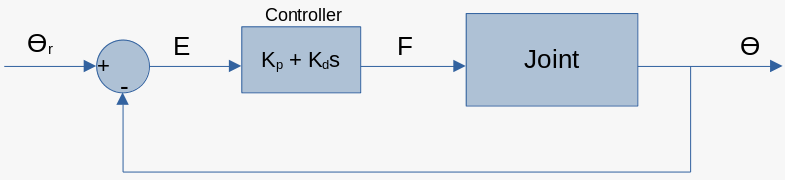

The overall formula for our controller is given as,


$$F=K_p E+K_d \dot{E} =K_p E-K_d v$$


In this formula, the error for our controller, $E$ is calculated as $E=\theta_r -\theta$. This error is then with the proportional multiplier (gain) $K_p$ to obtain the first term of our controller. For the second term, the derivative of the error is calculated as $\dot{E} =\dot{\theta_r } -\dot{\theta} =0-\dot{\theta} =-v$, i.e. the negative of the current velocities of the joints. This derivative of the error is then multiplied with the derivative gain, $K_d$.

For every moment in time, as we move our robot, we can use the controller formula to calculate the new set of forces that we would like to apply to our robot. By dividing the forces by the masses, we obtain the current linear accelerations we would like to apply to the joints. Then, we need to supply these current accelerations, current velocities, and current position to MATLAB's `inverseDynamics` in-built function, in order to output joint torques to apply to our motors.

Now let us set up some variables for our controller.

% Controller proportional gain
Kp = [50;40;600;0];
% Controller derivative gain
Kd = [6;10;11;0];
% Create timing array for controller to run
timeStep = 0.05; % arbitrarily small time step
timeLimit = 2000;
timeArr = 0:timeStep:timeLimit;
[~,timeArrLen] = size(timeArr);
% Starting positions, velocities, accelerations
jointPosCurr    = [0;0;0;0];
jointVelsCurr   = [0;0;0;0];
jointAccelsCurr = [0;0;0;0];
% Array for capturing joint torques
jointTorquesArr = zeros(4,1,timeArrLen);

Run our controller, and capture the joint torques.

i = 1;
goalNum = 1;
Kp_var = Kp;
Kd_var = Kd;
for t = timeArr
    % Current goal position
    currGoal = goalPos(:,:,goalNum);
    % Calculate error and error-derivative
    error = goalPos(:,:,goalNum) - jointPosCurr;
    error_prime = -1*jointVelsCurr;
    % Form forces
    F = Kp_var.*error + Kd_var.*error_prime;
    % Form new accelerations
    jointAccelsCurr = F./linkMass;
    % Get joint torques
    jointTorquesArr(:,:,i) = inverseDynamics(denso_robot,jointPosCurr,jointVelsCurr,jointAccelsCurr);
    i = i + 1;
    % Move the robot (update position and velocity)
    jointVelsCurr = jointVelsCurr + jointAccelsCurr*timeStep;
    jointPosCurr  = jointPosCurr + jointVelsCurr*timeStep
    % Check if we've reached goal within tolerance:
    % 0.05 radian and 0.01 m tolerance
    if (ismembertol(jointPosCurr(2,:),currGoal(2,:),0.2))
        Kp_var(1,1) = 0;
        Kp_var(2,1) = 0;
        Kd_var(1,1) = 0;
        Kd_var(2,1) = 0;
    end
    if (ismembertol(jointPosCurr(2,:),currGoal(2,:),0.2) && abs(error(3,1)) <= 0.01)
        fprintf("Reached goal %d\n",goalNum);
        goalNum = goalNum + 1;
        % Retract prismatic joint
        jointPosCurr(3,1) = 0;
        % Reset gains
        Kp_var = Kp;
        Kd_var = Kd;
    end
    % Check if we've reached all goals
    if (goalNum > 8)
        fprintf("Reached all goals, stopping.\n");
        break;
    end
end

jointPosCurr =          0
         0
   -0.1500
         0


jointPosCurr =          0
         0
   -0.2963
         0


jointPosCurr =          0
         0
   -0.3301
         0


jointPosCurr =          0
         0
   -0.2571
         0


jointPosCurr =          0
         0
   -0.1613
         0


jointPosCurr =          0
         0
   -0.1209
         0


jointPosCurr =          0
         0
   -0.1509
         0


jointPosCurr =          0
         0
   -0.2095
         0


jointPosCurr =          0
         0
   -0.2448
         0


Reached goal 1


jointPosCurr =     0.0364
    0.0095
   -0.1756
         0


jointPosCurr =     0.1039
    0.0265
   -0.3212
         0


jointPosCurr =     0.1968
    0.0489
   -0.3359
         0


jointPosCurr =     0.3085
    0.0750
   -0.2446
         0


jointPosCurr =     0.4326
    0.1032
   -0.1450
         0


jointPosCurr =     0.5625
    0.1320
   -0.1140
         0


jointPosCurr =     0.6925
    0.1602
   -0.1561
         0


jointPosCurr =     0.8169
    0.1871
   -0.2195
         0


jointPosCurr =     0.9312
    0.2117
   -0.2509
         0


jointPosCurr =     1.0455
    0.2364
   -0.2355
         0


jointPosCurr =     1.1598
    0.2611
   -0.1977
         0


jointPosCurr =     1.2741
    0.2858
   -0.1720
         0


Reached goal 2


jointPosCurr =     1.3294
    0.3003
   -0.1314
         0


jointPosCurr =     1.3292
    0.3061
   -0.2781
         0


jointPosCurr =     1.2790
    0.3044
   -0.3259
         0


jointPosCurr =     1.1861
    0.2967
   -0.2661
         0


jointPosCurr =     1.0585
    0.2844
   -0.1732
         0


jointPosCurr =     0.9050
    0.2688
   -0.1259
         0


jointPosCurr =     0.7346
    0.2509
   -0.1472
         0


jointPosCurr =     0.5560
    0.2320
   -0.2022
         0


jointPosCurr =     0.3777
    0.2128
   -0.2405
         0


jointPosCurr =     0.2068
    0.1942
   -0.2378
         0


jointPosCurr =     0.0499
    0.1766
   -0.2075
         0


jointPosCurr =    -0.0879
    0.1605
   -0.1799
         0


Reached goal 3


jointPosCurr =    -0.1683
    0.1638
   -0.1300
         0


jointPosCurr =    -0.1937
    0.1827
   -0.2767
         0


jointPosCurr =    -0.1684
    0.2138
   -0.3256
         0


jointPosCurr =    -0.0987
    0.2536
   -0.2668
         0


jointPosCurr =     0.0082
    0.2992
   -0.1741
         0


jointPosCurr =     0.1441
    0.3478
   -0.1263
         0


jointPosCurr =     0.3003
    0.3972
   -0.1469
         0


jointPosCurr =     0.4684
    0.4453
   -0.2017
         0


jointPosCurr =     0.6402
    0.4908
   -0.2401
         0


Reached goal 4


jointPosCurr =     0.8990
    0.5101
   -0.1779
         0


jointPosCurr =     1.2254
    0.5073
   -0.3234
         0


jointPosCurr =     1.5990
    0.4866
   -0.3364
         0


jointPosCurr =     1.9995
    0.4520
   -0.2435
         0


jointPosCurr =     2.4075
    0.4072
   -0.1435
         0


jointPosCurr =     2.8054
    0.3558
   -0.1134
         0


jointPosCurr =     3.1774
    0.3008
   -0.1565
         0


jointPosCurr =     3.5108
    0.2448
   -0.2204
         0


jointPosCurr = 4×1
    3.7954
    0.1901
   -0.2514
         0


jointPosCurr = 4×1
    4.0243
    0.1385
   -0.2353
         0


jointPosCurr = 4×1
    4.1936
    0.0912
   -0.1972
         0


jointPosCurr = 4×1
    4.3021
    0.0492
   -0.1716
         0


jointPosCurr = 4×1
    4.3514
    0.0130
   -0.1744
         0


jointPosCurr = 4×1
    4.3453
   -0.0171
   -0.1956
         0


jointPosCurr = 4×1
    4.2897
   -0.0410
   -0.2143
         0


jointPosCurr = 4×1
    4.1919
   -0.0592
   -0.2171
         0


jointPosCurr = 4×1
    4.0600
   -0.0718
   -0.2063
         0


jointPosCurr = 4×1
    3.9031
   -0.0796
   -0.1938
         0


jointPosCurr = 4×1
    3.7301
   -0.0831
   -0.1893
         0


jointPosCurr = 4×1
    3.5499
   -0.0829
   -0.1941
         0


jointPosCurr = 4×1
    3.3707
   -0.0797
   -0.2020
         0


jointPosCurr = 4×1
    3.1999
   -0.0742
   -0.2062
         0


jointPosCurr = 4×1
    3.0438
   -0.0670
   -0.2046
         0


jointPosCurr = 4×1
    2.9073
   -0.0587
   -0.2000
         0


jointPosCurr = 4×1
    2.7942
   -0.0497
   -0.1966
         0


jointPosCurr = 4×1
    2.7069
   -0.0406
   -0.1967
         0


jointPosCurr = 4×1
    2.6465
   -0.0317
   -0.1992
         0


jointPosCurr = 4×1
    2.6127
   -0.0232
   -0.2016
         0


jointPosCurr = 4×1
    2.6044
   -0.0154
   -0.2021
         0


jointPosCurr = 4×1
    2.6192
   -0.0085
   -0.2009
         0


jointPosCurr = 4×1
    2.6544
   -0.0025
   -0.1993
         0


jointPosCurr = 4×1
    2.7063
    0.0024
   -0.1987
         0


jointPosCurr = 4×1
    2.7712
    0.0064
   -0.1992
         0


jointPosCurr = 4×1
    2.8450
    0.0094
   -0.2002
         0


jointPosCurr = 4×1
    2.9238
    0.0116
   -0.2007
         0


jointPosCurr = 4×1
    3.0038
    0.0129
   -0.2006
         0


jointPosCurr = 4×1
    3.0815
    0.0135
   -0.2000
         0


jointPosCurr = 4×1
    3.1540
    0.0135
   -0.1996
         0


jointPosCurr = 4×1
    3.2187
    0.0130
   -0.1996
         0


jointPosCurr = 4×1
    3.2737
    0.0122
   -0.1999
         0


jointPosCurr = 4×1
    3.3177
    0.0110
   -0.2002
         0


jointPosCurr = 4×1
    3.3500
    0.0097
   -0.2003
         0


jointPosCurr = 4×1
    3.3703
    0.0082
   -0.2001
         0


jointPosCurr = 4×1
    3.3791
    0.0067
   -0.1999
         0


jointPosCurr = 4×1
    3.3772
    0.0053
   -0.1998
         0


jointPosCurr = 4×1
    3.3656
    0.0039
   -0.1999
         0


jointPosCurr = 4×1
    3.3458
    0.0026
   -0.2000
         0


jointPosCurr = 4×1
    3.3195
    0.0015
   -0.2001
         0


jointPosCurr = 4×1
    3.2884
    0.0005
   -0.2001
         0


jointPosCurr = 4×1
    3.2543
   -0.0003
   -0.2000
         0


jointPosCurr = 4×1
    3.2189
   -0.0010
   -0.2000
         0


jointPosCurr = 4×1
    3.1839
   -0.0015
   -0.1999
         0


jointPosCurr = 4×1
    3.1505
   -0.0019
   -0.2000
         0


jointPosCurr = 4×1
    3.1202
   -0.0021
   -0.2000
         0


jointPosCurr = 4×1
    3.0938
   -0.0022
   -0.2000
         0


jointPosCurr = 4×1
    3.0720
   -0.0022
   -0.2000
         0


jointPosCurr = 4×1
    3.0552
   -0.0021
   -0.2000
         0


jointPosCurr = 4×1
    3.0438
   -0.0020
   -0.2000
         0


jointPosCurr = 4×1
    3.0376
   -0.0018
   -0.2000
         0


jointPosCurr = 4×1
    3.0363
   -0.0016
   -0.2000
         0


jointPosCurr = 4×1
    3.0395
   -0.0014
   -0.2000
         0


jointPosCurr = 4×1
    3.0467
   -0.0011
   -0.2000
         0


jointPosCurr = 4×1
    3.0571
   -0.0009
   -0.2000
         0


jointPosCurr = 4×1
    3.0700
   -0.0007
   -0.2000
         0


jointPosCurr = 4×1
    3.0846
   -0.0004
   -0.2000
         0


jointPosCurr = 4×1
    3.1001
   -0.0003
   -0.2000
         0


jointPosCurr = 4×1
    3.1158
   -0.0001
   -0.2000
         0


jointPosCurr = 4×1
    3.1310
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1451
    0.0002
   -0.2000
         0


jointPosCurr = 4×1
    3.1576
    0.0002
   -0.2000
         0


jointPosCurr = 4×1
    3.1682
    0.0003
   -0.2000
         0


jointPosCurr = 4×1
    3.1767
    0.0003
   -0.2000
         0


jointPosCurr = 4×1
    3.1829
    0.0004
   -0.2000
         0


jointPosCurr = 4×1
    3.1867
    0.0004
   -0.2000
         0


jointPosCurr = 4×1
    3.1882
    0.0003
   -0.2000
         0


jointPosCurr = 4×1
    3.1877
    0.0003
   -0.2000
         0


jointPosCurr = 4×1
    3.1853
    0.0003
   -0.2000
         0


jointPosCurr = 4×1
    3.1813
    0.0003
   -0.2000
         0


jointPosCurr = 4×1
    3.1760
    0.0002
   -0.2000
         0


jointPosCurr = 4×1
    3.1699
    0.0002
   -0.2000
         0


jointPosCurr = 4×1
    3.1632
    0.0001
   -0.2000
         0


jointPosCurr = 4×1
    3.1562
    0.0001
   -0.2000
         0


jointPosCurr = 4×1
    3.1494
    0.0001
   -0.2000
         0


jointPosCurr = 4×1
    3.1429
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1370
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1318
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1276
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1244
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1223
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1211
   -0.0001
   -0.2000
         0


jointPosCurr = 4×1
    3.1210
   -0.0001
   -0.2000
         0


jointPosCurr = 4×1
    3.1217
   -0.0001
   -0.2000
         0


jointPosCurr = 4×1
    3.1231
   -0.0001
   -0.2000
         0


jointPosCurr = 4×1
    3.1252
   -0.0001
   -0.2000
         0


jointPosCurr = 4×1
    3.1278
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1306
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1337
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1368
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1397
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1425
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1449
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1470
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1486
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1498
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1505
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1507
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1506
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1501
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1493
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1483
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1470
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1457
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1444
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1430
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1417
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1406
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1396
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1388
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1382
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1378
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1376
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1376
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1377
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1380
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1384
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1389
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1395
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1401
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1407
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1413
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1418
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1423
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1427
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1430
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1432
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1433
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1434
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1434
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1433
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1431
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1429
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1426
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1424
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1421
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1419
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1414
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1412
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1410
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1409
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1408
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1408
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1408
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1408
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1409
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1410
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1411
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1412
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1413
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1414
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1415
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1417
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1418
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1419
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1419
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1419
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1419
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1419
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1419
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1419
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1418
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1418
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1417
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1417
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1415
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1415
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1415
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1415
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1414
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1414
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1414
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1414
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1415
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1415
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1415
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1415
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1415
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1417
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1417
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1417
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1417
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1417
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
   -0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


jointPosCurr = 4×1
    3.1416
    0.0000
   -0.2000
         0


### Plot Joint Torques

The objective of this problem is to plot the joint torques that we would apply to the robot joint motors. The following is the plot for the first three joints. We are not concerned with the fourth joint since that is the end-effector joint, which does not affect our robot trajectory.

jointTorquesArr;